# Parameter estimation of FA2 and FA3 models

## Open the model

modelName = 'FA234';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','0')
set_param(modelName + "/Manual Switch2",'sw','0')

## Estimation problem

You use measured data to estimate the model parameters.

Input is IPTG concentration (step).

Measured output data is concentation in the culture medium

- OD600

- Fatty acid

Parameters: 

## Define the estimation experiments

Load the measured data.

load("FA2Data.mat")
load("FA3Data.mat")

Concatenate FA2 and FA3 data (for FA3, only 100-uM-IPTG batch is available).

FA23Data = cat(2,FA2Data,FA3Data(:,5,:),...
                            FA3Data(:,5,:),...
                            FA3Data(:,5,:),...
                            FA3Data(:,5,:),...
                            FA3Data(:,5,:),...
                            FA3Data(:,5,:)); % 6 copies of the same dataset
FA23Data(2:7,2:end,2) = NaN(6,12); % clear interpolated datapoints

Create the input data.

samplingTime = FA23Data(:,1,1);
outputData = FA23Data(:,2:end,:); % remove the first column (Time column)
inputData = ones(8,1)*[0 10 40 100 400 1000 100 100 100 100 100 100]; % [uM]
modelSelection = ones(8,1)*[0 0 0 0 0 0 1 1 1 1 1 1]; % 0 for FA2, 1 for FA3 model 

Create an experiment object to store the measured input/output data. 

Exp = sdo.Experiment(modelName);
% sdo.Experiment object
% The OutputData property and other properties are empty

Create Simulink.SimulationData.Signal objects to store the measured outputs.

% IPTG input
IPTGSignal = Simulink.SimulationData.Signal;
IPTGSignal.Name = 'IPTG';
IPTGSignal.BlockPath = modelName + "/IPTG";
IPTGSignal.PortType  = 'inport';
IPTGSignal.PortIndex = 1;
IPTGSignal.Values    = timeseries(inputData(:,1),samplingTime);

% Model selection input
modelSignal = Simulink.SimulationData.Signal;
modelSignal.Name = 'IPTG';
modelSignal.BlockPath = modelName + "/Model selection";
modelSignal.PortType  = 'inport';
modelSignal.PortIndex = 2;
modelSignal.Values    = timeseries(modelSelection(:,1),samplingTime);

Exp.InputData = [IPTGSignal; modelSignal]; % add the signal object to the experiment

% OD600 output
OD600Signal = Simulink.SimulationData.Signal;
OD600Signal.Name = 'OD600';
OD600Signal.BlockPath = modelName + "/GainX";
OD600Signal.PortType = 'outport';
OD600Signal.PortIndex = 1;
OD600Signal.Values = timeseries(outputData(:,1,1),samplingTime);

% IPA output
FASignal = Simulink.SimulationData.Signal;
FASignal.Name = 'Fatty acid';
FASignal.BlockPath = modelName + "/GainFA";
FASignal.PortType = 'outport';
FASignal.PortIndex = 1;
FASignal.Values = timeseries(FA3Data(:,1,2),samplingTime);

Exp.OutputData = [OD600Signal; FASignal]; % add the signal object to the experiment

Define the seven experiments.

Exp = [Exp;Exp;Exp;Exp;Exp;Exp;Exp;Exp;Exp;Exp;Exp;Exp]; % copied FA3 datasets

for expIdx = 1:12
    Exp(expIdx).InputData(1).Values = timeseries(inputData(:,expIdx),samplingTime); % IPTG input
    Exp(expIdx).InputData(2).Values = timeseries(modelSelection(:,expIdx),samplingTime); % model selection (FA2/3)
    Exp(expIdx).OutputData(1).Values = timeseries(outputData(:,expIdx,1),samplingTime); % OD600
    Exp(expIdx).OutputData(2).Values = timeseries(outputData(:,expIdx,2),samplingTime); % Fatty acid
end

## Specify the parameters to estimate

Specify bounds for the parameter values based on the structure of the model.

parameters = readtable(append('Parameters_FA23.xlsx'));
p = sdo.getParameterFromModel(modelName,parameters.Name);

% the output argument 'p' is a Param.Continuous object
% scaling factor can be specified in the Param.Continuous object

for paramIdx = 1:height(parameters)
    p(paramIdx).Value = parameters.InitialGuess(paramIdx);
    p(paramIdx).Minimum = parameters.Minimum(paramIdx);
    p(paramIdx).Maximum = parameters.Maximum(paramIdx);
    p(paramIdx).Scale = parameters.Scale(paramIdx);
    p(paramIdx).Free = parameters.Free(paramIdx);
end

## Compare the measured output and the simulated output with the initial guess

Set the initial guess of the parameters to the experiment object and simulate. 

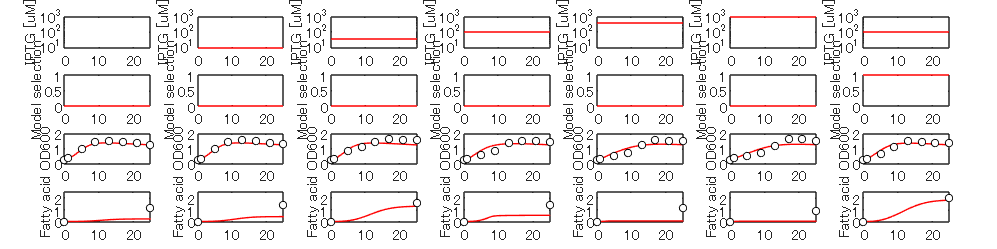

Exp = setEstimatedValues(Exp,p);
figure('Position', [100 100 1000 250]);
t = tiledlayout(4,7,'Padding','Compact','TileSpacing','tight');
t.TileIndexing = 'columnmajor';
for expIdx = 1:7 % FA3 copied datasets
    plotSimFA23(Exp,expIdx);
end

Check the objective function.

Simulator = createSimulator(Exp(1));
Error = estimation_Objective(p,Simulator,Exp,1:12,1:2,0,false,[1 4]);
fx = Error.F

fx = 57.0777

## Configure the simulator and model for Fast Restart

The simulator controls whether the model is simulated using fast restart or not. The `fastRestart` command is used to configure the simulator to use Fast Restart. 

The model uses a variable-step solver, and may not output values at the times in the measured experiment data. To output values at the times of the measured data, use the `set_param` command to specify the model logging output times as a workspace variable. In the estimation objective function, the variable is then used to specify output times to be the same as the measured experiment data. The model `OutputTimes` is set before configuring the simulator for fast restart, as once the model is configured for fast restart, the model logging configuration can not change.

Simulator = createSimulator(Exp(1));
modelName = Simulator.ModelName;
set_param(modelName,'OutputOption','SpecifiedOutputTimes', ...
    'OutputTimes','OutputTimesValues');
% 'OutputTimesValues' will be created in the objective function and assigned to the base
% workspace
Simulator = fastRestart(Simulator,'on');

The simulator can now be used during estimation, and the model will be simulated using fast restart.

## Define the estimation objective function

Create an estimation objective function to evaluate how closely the simulation outsput, generated using the estimated parameter values, matches the measured data.

Use an anonymous function with one input argument that calls the `cellCultureModel_Objective` function. Pass the anonymous function to `sdo.optimize`, which evaluates the function at each optimization iteration.

lambda = 0;         % regularization parameter
expToUse = 1:12;     % all datasets are used for training
outputToUse = 1:2;  % OD600 and Fatty acid data
Woutput = [1 4]; % weights for outputs
% estFcn = @(p) estimation_Objective_scholar(p,Simulator,Exp,expToUse,outputToUse,lambda);

## Estimate the parameters

Use the `sdo.optimize` function to estimate the actuator parameter values and initial state. 

Specify the optimization options. The estimation function `sdoAircraftEstimation_Objective` returns the error residuals between simulated and experimental data and does not include any constraints, making this problem ideal for the `lsqnonlin` solver.

options = sdo.OptimizeOptions;
options.Method = 'lsqnonlin';
% options.MethodOptions.MaxFunctionEvaluations = 1000;
options.UseParallel = 1;
options.OptimizedModel = modelName;

Create a cluster object

% SAVE THE MODEL!!
numWorkers = 3;
c = parcluster

c = 

 Generic Cluster

    プロパティ: 

                   Profile: cc21dev0_cluster_short R2022a
                  Modified: false
                      Host: LAPTOP-5PV3VUVE
                NumWorkers: 100
                NumThreads: 1

        JobStorageLocation: C:\Users\tomok\AppData\Roaming\MathWorks\MATLAB\3p_cluster_jobs\default_cluster\LAPTOP-5PV3VUVE\R2022a\nonshared
         ClusterMatlabRoot: /usr/local/MATLAB/R2022a/
           OperatingSystem: unix

   RequiresOnlineLicensing: false
     PluginScriptsLocation: C:\Users\tomok\MATLAB\slurm_integration\IntegrationScripts\default_cluster
      AdditionalProperties: 

pathToData = pwd

pathToData = 'C:\Users\tomok\MATLAB\Projects\HISICC2'

job = batch(c,@parallelEstimation,2,{p,Simulator,Exp,expToUse,outputToUse,lambda,options,Woutput}, ...
                "Pool",numWorkers, ...
                "CurrentFolder",'.', ...
                "AdditionalPaths",pathToData, ...
                "AttachedFiles",{append(modelName,'.slx'),'P_T7.m'} ...
            );

additionalSubmitArgs = '--ntasks=4 --cpus-per-task=1 --ntasks-per-core=1 --mem-per-cpu=7300MB -p cluster_short --time 4:00:00'

Check the state of the job.

job.State

ans = 'finished'

diary(job)

--- ダイアリ開始 ---

modelName =

    'FA234'


modelopened =

  logical

   1


isOutputVector =

  logical

   1

Configuring parallel workers for optimization...
Parallel workers configured for optimization.

 Optimization started 11-Nov-2023 21:31:49

                                          First-order 
 Iter F-count        f(x)      Step-size  optimality
    0     43      57.0791            1                                         
    1     86      22.3237       0.7024         43.6
    2    129      4.70073         0.73         10.7
    3    172      4.70073        1.478         10.7
    4    215      2.42735       0.3696         3.14
    5    258      1.71043       0.7392         7.68
    6    301      1.71043       0.4066         7.68
    7    344      1.32137       0.1016         1.32
    8    387      1.12844       0.2033        0.569
    9    430     0.921823       0.4066         2.58
   10    473     0.921823       0.9756         2.58
   11    516     0.818807       0.2033   

Get the printed log in the cluster.

getReport(job.Tasks(1).Error)

Fetch the results from the cluster.

if job.State == "finished"
    result = fetchOutputs(job);
    pOpt = result{1};
    optInfo = result{2};
end

delete(job)
clear job

Save the parameter estimation results.

save(append('pOpt_',modelName),'pOpt')
save(append('optInfo_',modelName),'optInfo')

## Calculate the confidence intervals

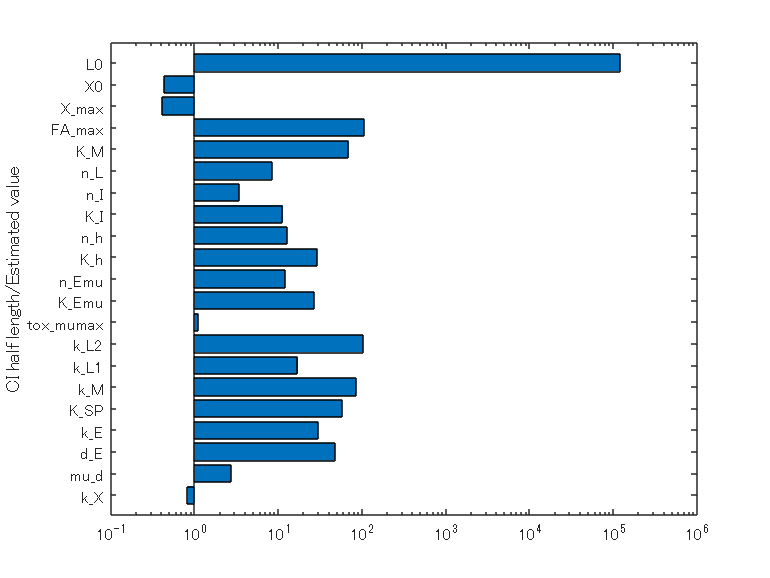

ci_ratio = plotCI(pOpt,optInfo);

## Restore the model

Restore the simulator fast restart settings. This clears the logging and other settings used for the optimization problem. 

Simulator = fastRestart(Simulator,'off');
set_param(modelName,'OutputOption','RefineOutputTimes','OutputTimes','[]');

## Compare the test data set and the simulated output

Update the experiments with the estimated parameter values.

Exp = setEstimatedValues(Exp,pOpt);

Simulate the model updated with the estimated parameter value and compare the simulated output with the experimental data. The model response using the estimated parameter values closely matches the experiment output data.

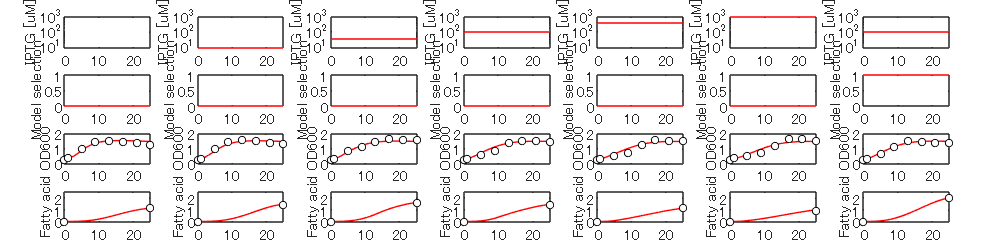

figure('Position', [100 100 1000 250]);
t = tiledlayout(4,7,'Padding','Compact','TileSpacing','tight');
t.TileIndexing = 'columnmajor';
for expIdx = 1:7 % test data set
    plotSimFA23(Exp,expIdx);
end

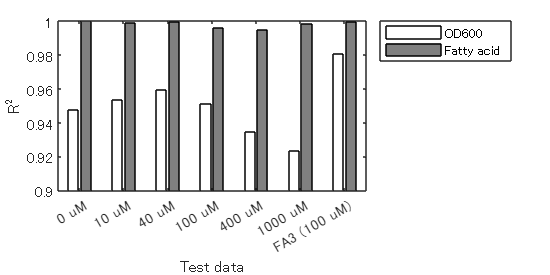

Simulator = createSimulator(Exp(1));
R2 = zeros(7,2);
for expIdx = 1:7 % test data set
    R2(expIdx,:) = rSquared(pOpt,Simulator,Exp,expIdx,1:2);
end

R2_OD600 = R2(:,1);
R2_FFA = R2(:,2);

figure('Position', [100 100 400 200]);
b = bar([R2_OD600,R2_FFA]);
xticklabels({'0 uM' '10 uM' '40 uM' '100 uM' '400 uM' '1000 uM' 'FA3 (100 uM)'})
xlabel('Test data')
ylabel('R^2')
ylim([0.9 1])
colororder({'w','#808080'})
legend({'OD600' 'Fatty acid'},'Location','northeastoutside')

sdo.setValueInModel(modelName,pOpt);

Close the model.

bdclose('cellCultureModel')

*Copyright Tomoki Ohkubo@NAIST*